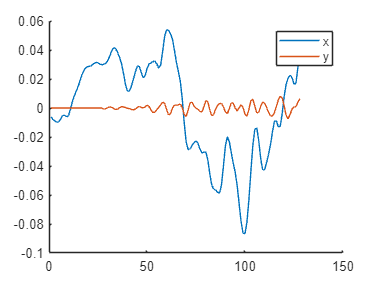

% INITIALIZE PARAMETERS
M = 26;                         % M-tap filter
N_FFT = 128;                    % number of samples for fft

%% READ INPUT SIGNAL
filename = 'guitar.wav';
[x,fs] = audioread(filename);   % fs = sampling frequency (usually 44100 Hz for audio)
x = x(1:3*fs);                  % select the 3 first seconds
N = length(x);                  % length returns number of elements in x
y = zeros(N,1);                 % zeros() creates an array of N values initialized to 0

%% DESIGNING a FIR FILTER
a = fir1(M, 10000/fs, 'high')'; % fir1 to design a FIR filter (frequency specification -> coefficients)
                                % fir1(number of coefficients, cut-off frequency, type of filter)                             
fvtool(a,1);                    % fvtool to visualise frequency response of a filter
M=length(a);                    % Make that M respresents the length of array a

%% PROCESSING OF INPUT SIGNAL
% a = ones(M,1) / M;            % ones() creates an array of Ms values initialized to 0

for i=(M+1):N                   
    vect = i-(M-1) : i;
    y(i) = sum(x(vect) .* a);
end

mag_fft_x = abs(fft(x(1:N_FFT)));
mag_fft_y = abs(fft(y(1:N_FFT)));

%% DISPLAY RESULTS
figure;
hold on; plot(x(1:N_FFT));
hold on; plot(y(1:N_FFT));
legend("x","y");

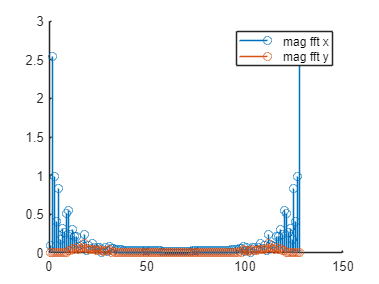


figure;
hold on; stem(mag_fft_x);
hold on; stem(mag_fft_y);
legend("mag fft x","mag fft y");


%% PLAY OUTPUT SIGNAL
sound(y, fs);